## Initial setup

Clears the workspace

clear

Call the diff_drive_IMU_sym_SLAM function

diff_drive_IMU_sym_SLAM

$$lm = \left(\begin{array}{cccccccccc} l_{1,1} & l_{1,2} & l_{1,3} & l_{1,4} & l_{1,5} & l_{1,6} & l_{1,7} & l_{1,8} & l_{1,9} & l_{1,10}\\ l_{2,1} & l_{2,2} & l_{2,3} & l_{2,4} & l_{2,5} & l_{2,6} & l_{2,7} & l_{2,8} & l_{2,9} & l_{2,10} \end{array}\right)$$

Initialize a 2D 90 degree rotation matrix.

R90=[0 -1;1 0];

How many seconds the simulation should run

T=100; %simulation time

How long each timestep should take.

dT=0.1; %simulation time step

Number of steps

N=ceil(T/dT);

Initialize an empty $2\times N$ matrix for the robot positions

x=zeros(2,N); %positions

Set the initial position of the Robot.

x(:,1)=[0;-5];

Initialize the heading matrix to have the same size as the position matrix. 

u=x; %headings

Create a control input vector to define the forward velocities. 

v=zeros(1,N); %forward velocities

Set the initial forward velocity to 1.

v(1)=1;

Set the initial heading to point along $+x$

u(:,1)=[1;0];

## Landmarks

th determines the angle wich the landmarks are placed around the origin

%landmark positions
th=(0:4)*2*pi/5;

Create the inner pentagon of landmarks, by using the angles from above.

%inner circle
l_inner=3*[cos(th+pi/2);sin(th+pi/2)];

Create the outer landmark pentagon, 

%outer circle
l_outer=7*[cos(th-pi/2);sin(th-pi/2)];

This is the vector with the actual landmarks. 

lm=[l_inner l_outer];

This is the vector which is supposed to contain the found landmarks as a high initial number.

%recorded landmarks
lm_found=[1e6;1e6] %initial dummy

lm_found =      1000000
     1000000


We make the esimate of the state vector. which contains

$x_{t+1} =\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack \\
v\\
\left\lbrack \begin{array}{c}
u_x \\
u_y 
\end{array}\right\rbrack \\
10\left\lbrack \begin{array}{c}
l_x \\
l_y 
\end{array}\right\rbrack 
\end{array}\right\rbrack$ where x is the robot position. v is the magnometer. u is the heading unit vector. l is the landmarks, and there is 10 landmarks. 

The  $X_{\mathrm{est}} \in {\mathbb{R}}^{25\times N}$ where N is also the number of steps. 

%estimated state
X_est=zeros(2+1+2+2*10,N); %x,v,u,l * 10

Set the first robot position $x_0$ to the actual position. This means that we are completely certain about the robots initial configuration based on the proprioceptive information. 

X_est(1:2,1)=x(:,1);
X_est(3,1)=v(1);
X_est(4:5,1)=u(:,1);

We initialize the covariance matrix, with 20% variance of the first 5 states, correspondig to the position, magnotometer and the heading. 

%Noise covariances
Q=diag(0.2*[ones(1,2+1+2) 0*ones(1,2*10)]);

Initialize the measurement white noise. 

Rl=eye(3);

Create the P covariance matrix which is the initial state covariance matrix. 

P=eye(2+1+2+2*10);

Set the first $7\times 7$ part of the matrix to 0. 

P(1:7,1:7)=zeros(7,7);

Start the simulation

for i=1:N-1

Initialize the acceleration and the angular velocity.

    a=0.001;
    omega=1/5;

Sample noise of the heading.

    %Simulation time step
    rrand=randn(1)*0.2;

We set the next actual state of the robot, i.e. the **True state**, which is only used for plotting. This is also here where the robot drive in random circles. 

    [X,U,V]=diff_drive_IMU(x(:,i),u(:,i),v(i),omega+rrand,a,dT);
    x(:,i+1)=X;
    u(:,i+1)=U;
    v(i+1)=V;    

Now we predict the next state of the robot, based on $x_{t-1} ,u_{t-1} ,v_{t-1}$. We then put the estimated values in the X_est variables 

    %state prediction for robot states
    [X_pred,U_pred,V_pred]=diff_drive_IMU(X_est(1:2,i),X_est(4:5,i),X_est(3,i),omega,a,dT);
    X_est(1:2,i+1)=X_pred;
    X_est(4:5,i+1)=U_pred;
    X_est(3,i+1)=V_pred;

We estimate the position of the landmarks, but they are static

    %prediction of landmarks - constant predictor
    X_est(2+1+2+1:end,i+1)=X_est(2+1+2+1:end,i);


 Compute the difference between the robot position and the landmarks

    %compute distances to landmarks
    diff=x(:,i)*ones(1,10)-lm;

Calculate the distance to the landmarks using euclidean distance

    dist=diff(1,:).^2+diff(2,:).^2;

it finds all landmarks within the range of the lidar which is set to 3 m. Note 3 m becuase the euclidean distance function is not sqrt. 

    I=find(dist<3^2);  

Clear the landmark location variable lm_loc

  
    %determine positions of landmarks in sight
    %find angle and distance
    clear lm_loc

Loop though all the found landmarks

    for k=1:length(I)

We find the current distance to the current landmark from the current true state. 

        d=norm(x(:,i)-lm(:,I(k))); 

We find the estimated distance to the current landmark based on the estimated states. 

        d_est=norm(X_est(1:2,i)-lm(:,I(k)));

$u=\left\lbrack \begin{array}{c}
{\textrm{uu}}_1 \\
{\textrm{uu}}_2 
\end{array}\right\rbrack$ is the heading vector from the robot position to the landmark. ${\mathrm{uu}}_2$ is rotated 90 degress with respect to ${\textrm{uu}}_1$. because we need two scalars to describe orientation in a 2D space

We find the heading vector from the current position of the robot to the landmark for x

        uu1=(lm(:,I(k))-x(:,i))'*u(:,i)/d;

Same for y

        uu2=(lm(:,I(k))-x(:,i))'*(R90*u(:,i))/d;

We combine the found orientation and translation to esitmate the landmark position in global coordinates

        lm_loc(:,k)=d*(uu1*X_est(4:5,i)+uu2*R90*X_est(4:5,i))+X_est(1:2,i); %estimated landmark position in global coordinates

$y_{\textrm{meas}}$ is a vector that holds the measurement from the current robot position

        y_meas=[d^2;uu1;uu2];

Compute the difference vector to the found landmarks with respect to the located landmark

        %compute distances to found landmarks - should be from X_est
        diff=lm_loc(:,k)*ones(1,length(lm_found))-lm_found;

Next we find the distance vector, being a $1\times 11$vector with the first entry being our starting point, from the robot position to the landmarks

        dist=diff(1,:).^2+diff(2,:).^2;

Then we find the closest landmark

        [HH II]=min(dist);
        %HH

We use a validation gate to verify if the distances from the found landmark is close enough to the actual landmark. This is the matching step. If distance is above $1\ldotp 2^2$ we consider it as a new landmark, and add it to the list of landmarks and into the estimated statevector. 

        if(HH>1.2^2) %new landmark detected
            lm_found=[lm_found lm_loc(:,k)]; %insert newly found landmark
            lm_index=2+1+2+2*(size(lm_found,2)-1)-1;
            %insert landmark in estimated state vector
            X_est(lm_index:lm_index+1,i+1)=lm_loc(:,k);
            

If the estimated distance from our sensor model to the landmark is greater than $0\ldotp 2$ we have loop closure. 

        elseif(d_est>0.2)%old landmark revisited
            %use landmark for EKF
            %disp('correction')
            %compute EKF matrices
            clear F

We update the motion jacobian as numbers. 

            F=FNum(dT,omega,X_est(4,i+1),X_est(5,i+1),X_est(3,i+1));
            lm_index=2+1+2+2*(II-1)-1;

We compute the measurement jacobian. 

            H=H3{II-1}(lm_found(1,II),lm_found(2,II),X_est(4,i+1),X_est(5,i+1),X_est(1,i+1),X_est(2,i+1));            

We predict the distance measurement from the robot to the landmark.

            %compute predicted measurement
            d_pred=norm(X_est(1:2,i+1)-X_est(lm_index:lm_index+1,i+1));

Then we find the predicted coordinates of the heading vector to the from the robot to the landmark 

            uu1_pred=(X_est(lm_index:lm_index+1,i+1)-X_est(1:2,i+1))'*X_est(4:5,i+1)/d;
            uu2_pred=(X_est(lm_index:lm_index+1,i+1)-X_est(1:2,i+1))'*(R90*X_est(4:5,i+1))/d;

We concatenate into the y vector. 

            y_pred=[d_pred^2;uu1_pred;uu2_pred]; %predicted output

We update the residual covariance matrix based on the motion jacobians plus the motion noise Q. 

            %EKF correction equations
            P=F*P*F'+Q; %residual covariance

We update the the measurements using the measurement jacobian $H$ and the residual covariance $P$ plus the measurement noise. 

            S=H*P*H'+Rl;

We compute the Kalman gain. 

            K=P*H'*inv(S);
            %y_meas-y_pred

We update the state estimation using the kalman gain using the innovation. 

            X_est(:,i+1)=X_est(:,i+1)+K*(y_meas-y_pred);

Update the risidual covariance matrix. 

            P=(eye(2+1+2+2*10)-K*H)*P;
            figure(2)
            mesh(P(6:end,6:end))
        end
    end
    
    

Handle plotting

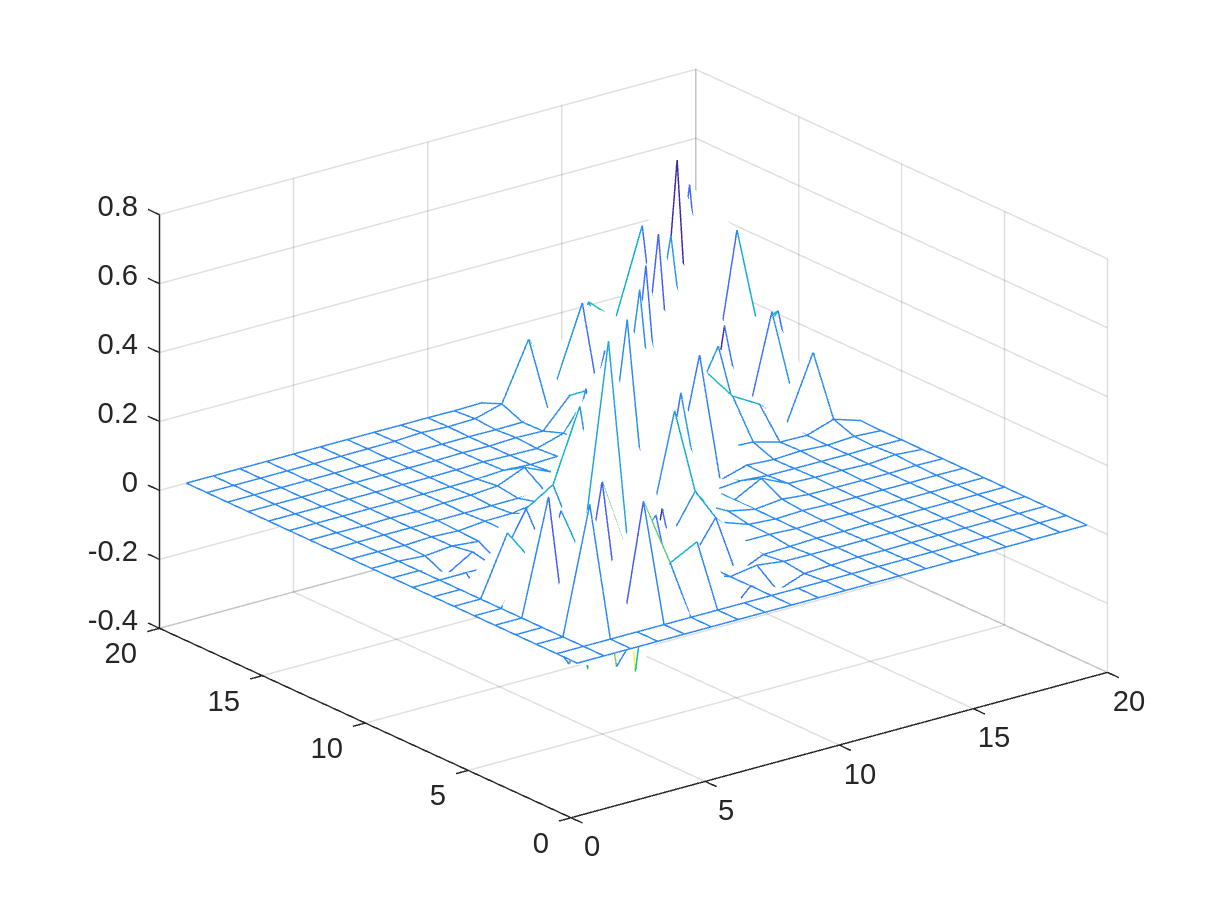

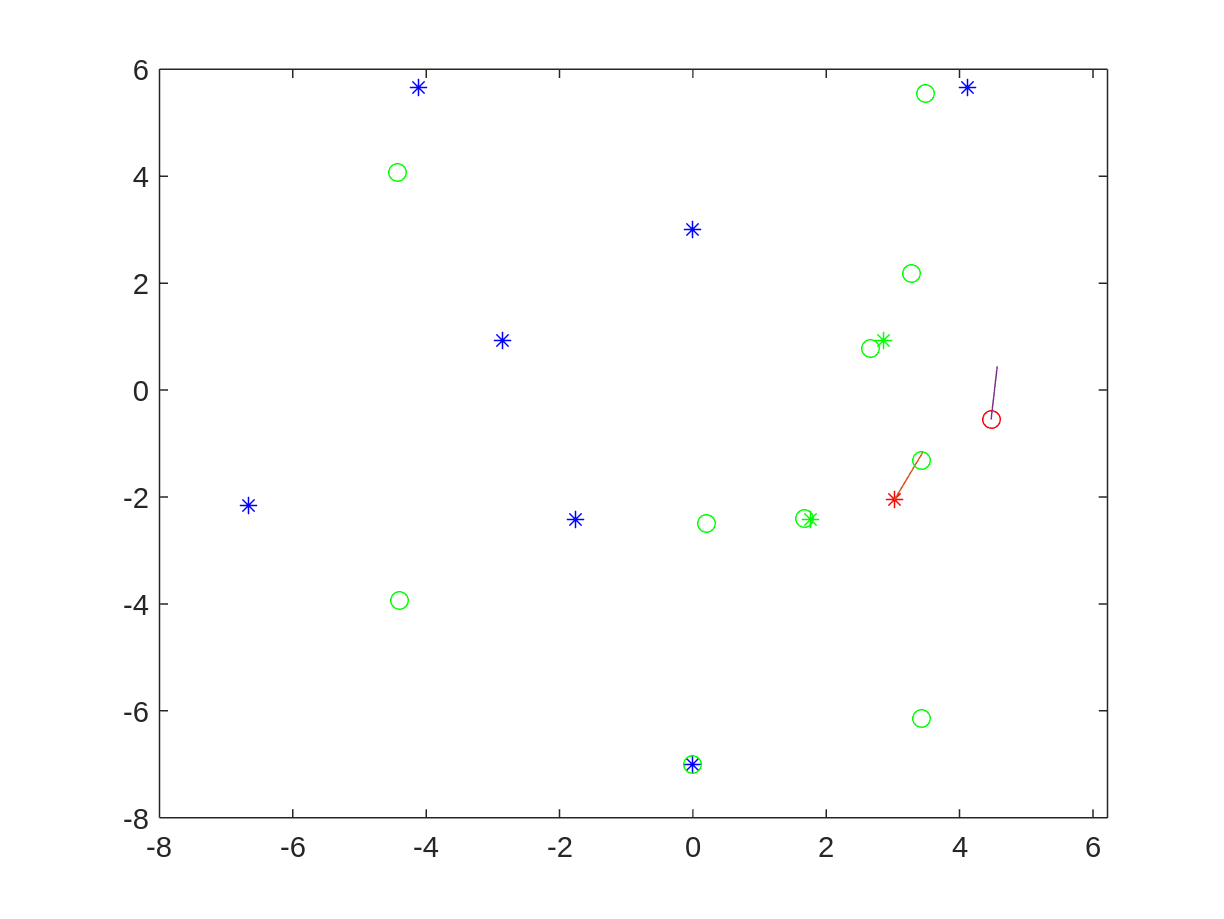

Arrays have incompatible sizes for this operation.

Related documentation

    figure(1)
    clf
    plot(x(1,i),x(2,i),'r*')
    hold on
    plot([x(1,i) x(1,i)+u(1,i)],[x(2,i) x(2,i)+u(2,i)])
    plot(X_est(1,i),X_est(2,i),'ro')
    plot([X_est(1,i) X_est(1,i)+X_est(4,i)],[X_est(2,i) X_est(2,i)+X_est(5,i)])
    plot(lm(1,:),lm(2,:),'b*')
    plot(lm(1,I),lm(2,I),'g*')
    plot(lm_found(1,2:end),lm_found(2,2:end),'go')
    pause(0.01)
    i;
end

plot(x(1,:),x(2,:),lm(1,:),lm(2,:),'*')
hold on
plot(X_est(1,:),X_est(2,:),'.')
l_est=X_est(2+1+2+1:end,i);
plot(l_est(1:2:end-1),l_est(2:2:end),'bo')

# Run the program and record the covariance in of the landmark position discovered last. 

The landmark has no covaraince, it is measured to be 0. This is suspected to be a single landmark that just did not make the validation gate, so it was initially considered a new one, but then it was matched in every other itteration. 

# Modify the program (take a copy) so that the landmarks are distributed evenly over a straight line connecting end-points (0,6) and (30,6)

## Initial setup

Clears the workspace

clear all

Call the diff_drive_IMU_sym_SLAM function

diff_drive_IMU_sym_SLAM

$$lm = \left(\begin{array}{cccccccccc} l_{1,1} & l_{1,2} & l_{1,3} & l_{1,4} & l_{1,5} & l_{1,6} & l_{1,7} & l_{1,8} & l_{1,9} & l_{1,10}\\ l_{2,1} & l_{2,2} & l_{2,3} & l_{2,4} & l_{2,5} & l_{2,6} & l_{2,7} & l_{2,8} & l_{2,9} & l_{2,10} \end{array}\right)$$

Initialize a 2D 90 degree rotation matrix.

R90=[0 -1;1 0];

How many seconds the simulation should run

T=30; %simulation time

How long each timestep should take.

dT=0.1; %simulation time step

Number of steps

N=ceil(T/dT);

Initialize an empty $2\times N$ matrix for the robot positions

x=zeros(2,N); %positions

Set the initial position of the Robot.

x(:,1)=[0;0];

Initialize the heading matrix to have the same size as the position matrix. 

u=x; %headings

Create a control input vector to define the forward velocities. 

v=zeros(1,N); %forward velocities

Set the initial forward velocity to 1.

v(1)=1;

Set the initial heading to point along $+x$

u(:,1)=[1;0];

## Landmarks

Linspace 10 landmarks from $\left(0,6\right)$ to $\left(30,6\right)$

lm_x = linspace(0,30, 10);
lm_y = ones([1, 10])*6;
lm=[lm_x; lm_y]

lm =          0    3.3333    6.6667   10.0000   13.3333   16.6667   20.0000   23.3333   26.6667   30.0000
    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000


This is the vector which is supposed to contain the found landmarks as a high initial number.

%recorded landmarks
lm_found=[1e6;1e6] %initial dummy

lm_found =      1000000
     1000000


We make the esimate of the state vector. which contains

$x_{t+1} =\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack \\
v\\
\left\lbrack \begin{array}{c}
u_x \\
u_y 
\end{array}\right\rbrack \\
10\left\lbrack \begin{array}{c}
l_x \\
l_y 
\end{array}\right\rbrack 
\end{array}\right\rbrack$ where x is the robot position. v is the magnometer. u is the heading unit vector. l is the landmarks, and there is 10 landmarks. 

The  $X_{\textrm{est}} \in {\mathbb{R}}^{25\times N}$ where N is also the number of steps. 

%estimated state
X_est=zeros(2+1+2+2*10,N); %x,v,u,l * 10

Set the first robot position $x_0$ to the actual position. This means that we are completely certain about the robots initial configuration based on the proprioceptive information. 

X_est(1:2,1)=x(:,1);
X_est(3,1)=v(1);
X_est(4:5,1)=u(:,1);

We initialize the motion model noise covariance matrix, with 20% variance of the first 5 states, correspondig to the position, magnotometer and the heading. 

%Noise covariances
Q=diag(0.2*[ones(1,2+1+2) 0*ones(1,2*10)]);

Initialize the measurement white noise. 

Rl=eye(3);

Create the P covariance matrix which is the initial state covariance matrix. 

P=eye(2+1+2+2*10);

Set the first $7\times 7$ part of the matrix to 0. 

P(1:7,1:7)=zeros(7,7);

Start the simulation

for i=1:N-1

Initialize the acceleration and the angular velocity.

    a=0.001;
    omega=0;

Sample noise of the heading.

    %Simulation time step
    rrand=randn(1)*0.2;

We set the next actual state of the robot, i.e. the **True state**, which is only used for plotting. This is also here where the robot drive in random circles. 

    [X,U,V]=diff_drive_IMU(x(:,i),u(:,i),v(i),omega+rrand,a,dT);
    x(:,i+1)=X;
    u(:,i+1)=U;
    v(i+1)=V;    

Now we predict the next state of the robot, based on $x_{t-1} ,u_{t-1} ,v_{t-1}$. We then put the estimated values in the X_est variables 

    %state prediction for robot states
    [X_pred,U_pred,V_pred]=diff_drive_IMU(X_est(1:2,i),X_est(4:5,i),X_est(3,i),omega,a,dT);
    X_est(1:2,i+1)=X_pred;
    X_est(4:5,i+1)=U_pred;
    X_est(3,i+1)=V_pred;

We estimate the position of the landmarks, but they are static

    %prediction of landmarks - constant predictor
    X_est(2+1+2+1:end,i+1)=X_est(2+1+2+1:end,i);


 Compute the difference between the robot position and the landmarks

    %compute distances to landmarks
    diff=x(:,i)*ones(1,10)-lm;

Calculate the distance to the landmarks using euclidean distance

    dist=diff(1,:).^2+diff(2,:).^2;

it finds all landmarks within the range of the lidar which is set to 3 m. Note 3 m becuase the euclidean distance function is not sqrt. 

    I=find(dist<6.5^2);  

Clear the landmark location variable lm_loc

  
    %determine positions of landmarks in sight
    %find angle and distance
    clear lm_loc

Loop though all the found landmarks

    for k=1:length(I)

We find the current distance to the current landmark from the current true state. 

        d=norm(x(:,i)-lm(:,I(k))); 

We find the estimated distance to the current landmark based on the estimated states. 

        d_est=norm(X_est(1:2,i)-lm(:,I(k)));

$u=\left\lbrack \begin{array}{c}
{\textrm{uu}}_1 \\
{\textrm{uu}}_2 
\end{array}\right\rbrack$ is the heading vector from the robot position to the landmark. ${\textrm{uu}}_2$ is rotated 90 degress with respect to ${\textrm{uu}}_1$. because we need two scalars to describe orientation in a 2D space

We find the heading vector from the current position of the robot to the landmark for x

        uu1=(lm(:,I(k))-x(:,i))'*u(:,i)/d;

Same for y

        uu2=(lm(:,I(k))-x(:,i))'*(R90*u(:,i))/d;

We combine the found orientation and translation to esitmate the landmark position in global coordinates

        lm_loc(:,k)=d*(uu1*X_est(4:5,i)+uu2*R90*X_est(4:5,i))+X_est(1:2,i); %estimated landmark position in global coordinates

$y_{\textrm{meas}}$ is a vector that holds the measurement from the current robot position

        y_meas=[d^2;uu1;uu2];

Compute the difference vector to the found landmarks with respect to the located landmark

        %compute distances to found landmarks - should be from X_est
        diff=lm_loc(:,k)*ones(1,length(lm_found))-lm_found;

Next we find the distance vector, being a $1\times 11$vector with the first entry being our starting point, from the robot position to the landmarks

        dist=diff(1,:).^2+diff(2,:).^2;

Then we find the closest landmark

        [HH II]=min(dist);
        %HH

We use a validation gate to verify if the distances from the found landmark is close enough to the actual landmark. This is the matching step. If distance is above $1\ldotp 2^2$ we consider it as a new landmark, and add it to the list of landmarks and into the estimated statevector. 

        if(HH>1.2^2) %new landmark detected
            lm_found=[lm_found lm_loc(:,k)]; %insert newly found landmark
            lm_index=2+1+2+2*(size(lm_found,2)-1)-1;
            %insert landmark in estimated state vector
            X_est(lm_index:lm_index+1,i+1)=lm_loc(:,k);
            

If the estimated distance from our sensor model to the landmark is greater than $0\ldotp 2$ we have loop closure. 

        elseif(d_est>0.2)%old landmark revisited
            %use landmark for EKF
            %disp('correction')
            %compute EKF matrices
            clear F

We update the motion jacobian as numbers. 

            F=FNum(dT,omega,X_est(4,i+1),X_est(5,i+1),X_est(3,i+1));
            lm_index=2+1+2+2*(II-1)-1;

We compute the measurement jacobian. 

            H=H3{II-1}(lm_found(1,II),lm_found(2,II),X_est(4,i+1),X_est(5,i+1),X_est(1,i+1),X_est(2,i+1));            

We predict the distance measurement from the robot to the landmark.

            %compute predicted measurement
            d_pred=norm(X_est(1:2,i+1)-X_est(lm_index:lm_index+1,i+1));

Then we find the predicted coordinates of the heading vector to the from the robot to the landmark 

            uu1_pred=(X_est(lm_index:lm_index+1,i+1)-X_est(1:2,i+1))'*X_est(4:5,i+1)/d;
            uu2_pred=(X_est(lm_index:lm_index+1,i+1)-X_est(1:2,i+1))'*(R90*X_est(4:5,i+1))/d;

We concatenate into the y vector. 

            y_pred=[d_pred^2;uu1_pred;uu2_pred]; %predicted output

We update the residual covariance matrix based on the motion jacobians plus the motion noise Q. 

            %EKF correction equations
            P=F*P*F'+Q; %residual covariance

We update the the measurements using the measurement jacobian $H$ and the residual covariance $P$ plus the measurement noise. 

            S=H*P*H'+Rl;

We compute the Kalman gain. 

            K=P*H'*inv(S);
            %y_meas-y_pred

We update the state estimation using the kalman gain using the innovation. 

            X_est(:,i+1)=X_est(:,i+1)+K*(y_meas-y_pred);

Update the risidual covariance matrix. 

            P=(eye(2+1+2+2*10)-K*H)*P;
            figure(2)
            mesh(P(6:end,6:end))
        end
    end
    
    

Handle plotting

    figure(1)
    clf

Plot the actual state of the robot. 

    plot(x(1,i),x(2,i),'r*')
    hold on
    plot([x(1,i) x(1,i)+u(1,i)],[x(2,i) x(2,i)+u(2,i)])
    plot(X_est(1,i),X_est(2,i),'ro')

Plot the estimated state as a hollow circle with a unit length vector as heading 

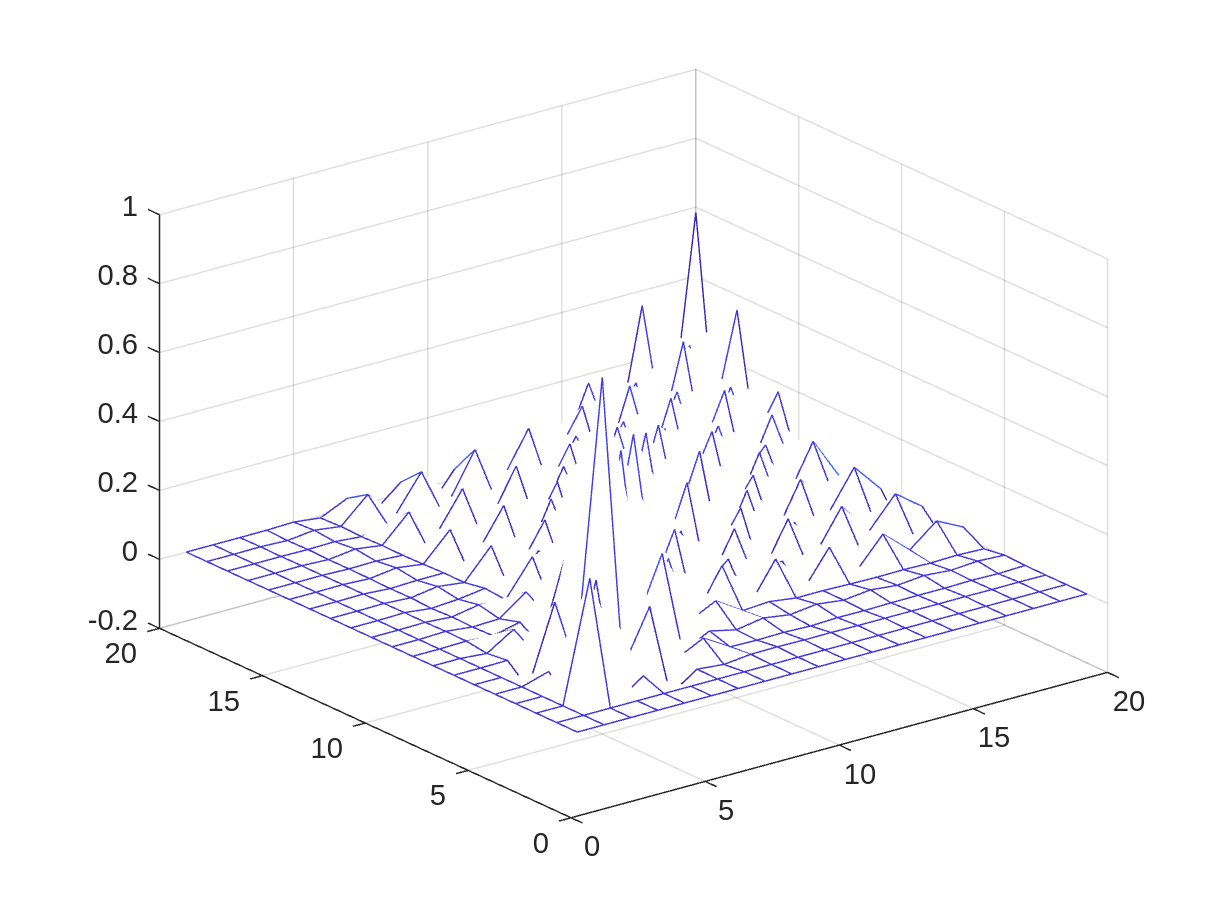

    plot([X_est(1,i) X_est(1,i)+X_est(4,i)],[X_est(2,i) X_est(2,i)+X_est(5,i)], 'green')
    plot(lm(1,:),lm(2,:),'b*')
    plot(lm(1,I),lm(2,I),'g*')
    plot(lm_found(1,2:end),lm_found(2,2:end),'go')
    pause(0.01)
    i;
end

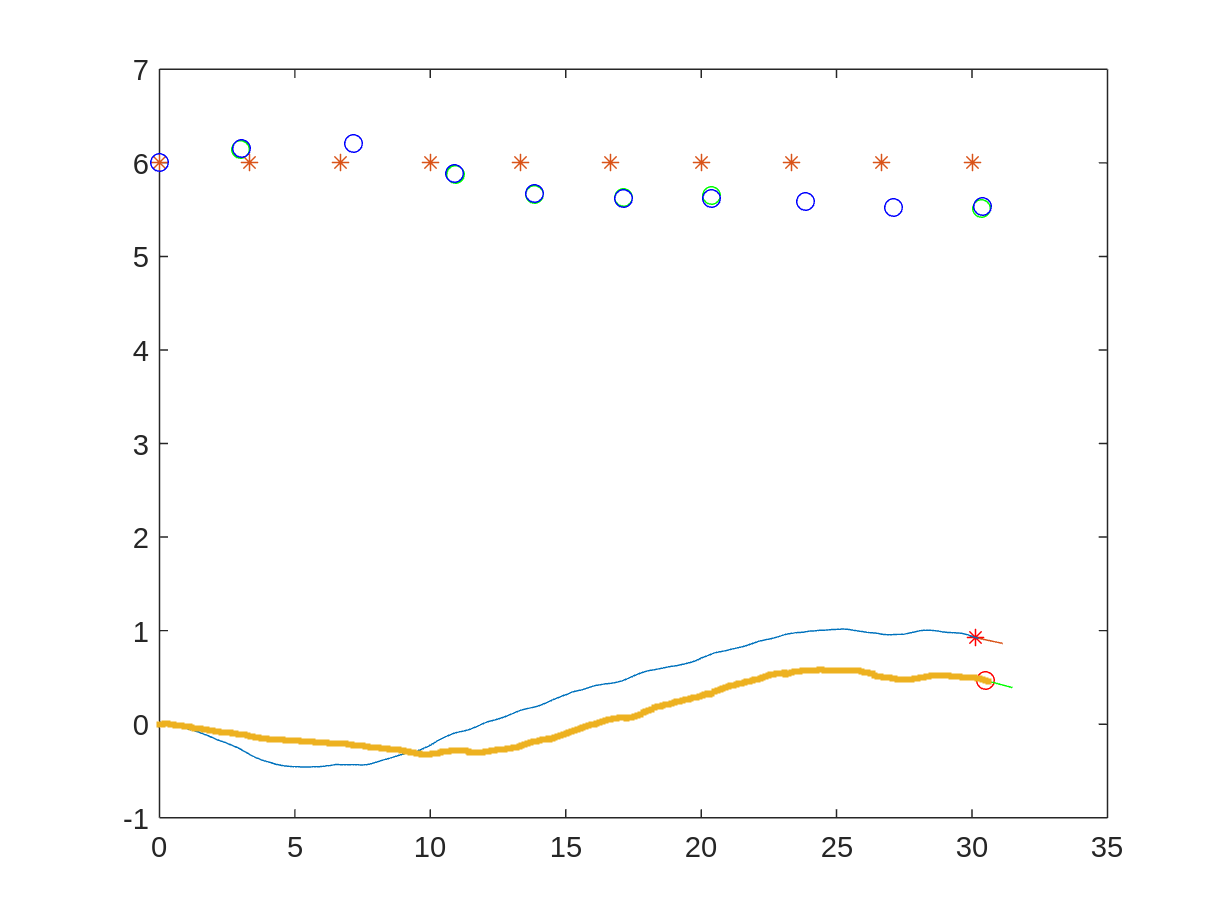

plot(x(1,:),x(2,:),lm(1,:),lm(2,:),'*')
hold on
plot(X_est(1,:),X_est(2,:),'.')
l_est=X_est(2+1+2+1:end,i);
plot(l_est(1:2:end-1),l_est(2:2:end),'bo')

# Modify further so, that the robot moves along a the line connecting points (0,0) and (30,0) and record the covariance. 

So the covariance matrix was not updated at all since the landmarks were never observed, since the detection distance is 3 m.  Sometimes it moves up to the landmarks based on the noise on the heading which has 0.2 variance. 

# Let the robot travel (0,0) to (30,0) and back and compare the previous results of covariance. 

Due to the random behavior of the robot heading, the results are inconsistent, but what i would expect to observe is that as soon as it is able to correcly observe and match the first landmark, which is precicesely known, then the covariances would be greatly reduced since we have loop closure. 